# LAB5_part3

Seyyed Mohammad Matin Alemohammad (810197457)

Amirhossein Mohammadi (810197689)

clc
clear
close all
rng(1)
dcl_init

if flg_add_hdr
    hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
    b_tx = [hder_bit; bit_gen(pkt_size-length(hder_bit), k)];
else
    b_tx = bit_gen(pkt_size, k);
end

b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


dec = bi2de(b_tx, 'left-msb');
dec_gray = bi2de(b_gray, 'left-msb');
sym_idx = zeros(pkt_size, 1);
if flg_gray_encode
    for i=1:M
        sym_idx(dec == dec_gray(i))= i-1;
    end
else
    sym_idx = dec;
end
disp(sym_idx);

     3
     0
     0
     0
     0
     0
     3
     3
     0
     3
     3
     0
     3
     3
     0
     0
     0
     0
     0
     3
     3
     3
     3
     0
     3
     3
     3
     3
     3
     3
     3
     3
     3
     0
     3
     0
     3
     0
     3
     3
     0
     3
     0
     3
     0
     0
     3
     0
     3
     3
     3
     3
     0
     3
     0
     3
     3
     3
     0
     0
     0
     3
     0
     0
     3
     0
     3
     0
     0
     0
     3
     3
     0
     0
     0
     3
     3
     0
     0
     3
     3
     0
     3
     0
     3
     0
     0
     3
     3
     0
     3
     0
     0
     0
     0
     3
     3
     0
     3
     3
     0
     0
     3
     3
     3
     0
     3
     0
     0
     2
     1
     0
     1
     1
     1
     0
     0
     3
     0
     3
     1
     2
     1
     2
     1
     2
     1
     0
     3
     3
     1
     2
     3
     3
     0
     1
     0
     2
     0
     1
     2
     2
     3

[cons, Es_avg] = constellation(M, modulation);
mod_sym = cons(sym_idx+1)

mod_sym =   -0.0000 - 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


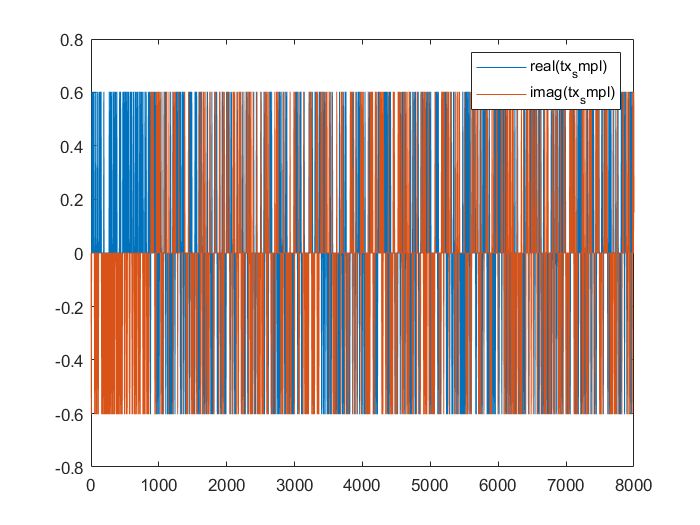

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_gen_mode);
if flg_add_hdr
    hder_smpl = tx_smpl(1:size(hder_bit, 1)*smpl_per_symbl);
    hder_auto_corr = xcorr(hder_smpl, hder_smpl);
%     hder_auto_corr = hder_auto_corr(length(hder_smpl):end);
end
plot(real(tx_smpl))
hold on
plot(imag(tx_smpl))
legend("real(tx_smpl)", "imag(tx_smpl)")
hold off

tx_smpl

tx_smpl =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


% rx_data = tx_smpl;
% rx_data_real = real(rx_data);
% rx_data_imag = imag(rx_data);
% rx_data_no_dc = rx_data - mean(rx_data);
% 
% rx_fft = fftshift(fft(rx_data)/frame_size);
% rx_fft_dBm = 10*log10(abs(rx_fft).^2/(2*R)*1000) - rx_gain;
% rx_fft_dBm_max = max(rx_fft_dBm_max, rx_fft_dBm);

% tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1) ; tx_smpl];

% rx_smpl = tx_smpl_delayed*exp(1i*chnl_phase_offset);

% Eb = Es_avg/k;
% ber = zeros(numel(snr_db), 1);
% ber_mat = zeros(numel(snr_db), 1);
% 
% for i = snr_min:snr_max %dB
%     snr = i;
%     var_noise = Eb/(10^(0.1*snr));
%     noise_smpl = sqrt(var_noise/2)*randn(length(rx_smpl), 1) + 1i*sqrt(var_noise/2)*randn(length(rx_smpl), 1);
%     rx_smpl_noise = rx_smpl + noise_smpl
%     
%     new_rx_smpl = rx_smpl_noise;
%     if flg_add_hdr
%         [corr_rx_hder, lag] = xcorr(rx_smpl_noise, hder_smpl);
%         corr_rx_hder = corr_rx_hder(lag>=0);
%         [hdr_corr_max, idx_max] = max(abs(corr_rx_hder));
%         corr_out_rx_max = corr_rx_hder(idx_max);
%         new_rx_smpl = new_rx_smpl(idx_max : end);
%         if cmpnst_mode == 1
%             new_rx_smpl = new_rx_smpl * max(abs(hder_auto_corr))/hdr_corr_max;
%         elseif cmpnst_mode == 2
%             new_rx_smpl = new_rx_smpl * exp(-1i*angle(corr_out_rx_max));
%         end
%         
%     end
%         [det_sym_idx, rx_sym] = pulse_demodulation(new_rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, rx_type);
%         
%         scatter(real(rx_sym), imag(rx_sym))
%         xlim([-1.5 1.5])
%         ylim([-1.5 1.5])
%         title(sprintf('%d %s', M, upper(modulation)))
%         grid on
%         
%         if flg_gray_encode
%             det_bit = b_gray(det_sym_idx, :);
%             det_bit_dec = bi2de(det_bit, 'left-msb');
%         else
%             det_bit = flip(de2bi(det_sym_idx-1), 2);
%         end
%         
%         det_bit = det_bit(1:size(b_tx, 1), :);
%         ber(i+1) = sum(det_bit ~= b_tx, 'all')/length(b_tx)/k;
%         ber_mat(i+1) = berawgn(snr, modulation, M, 'non-diff');
% end
%     
%     semilogy(snr_db, ber, snr_db, ber_mat);
%     grid on
%     title(sprintf('%d %s', M, upper(modulation)))

%     
% 